# 任务四：储能选址定容与交流潮流校核

学号：206221321；算例：49节点农村配电网；候选节点：4、9、14。

Stu_ID = '206221321';
% Live Editor 的未保存运行可能使用临时执行文件，先定位真实文档目录。
entry_name = ['maoyang_' Stu_ID '_Week2'];
project_candidates = {};
try
    active_file = matlab.desktop.editor.getActiveFilename;
    [active_dir,active_name] = fileparts(active_file);
    if strcmp(active_name,entry_name)
        project_candidates{end+1} = active_dir;
    end
catch
    % 无编辑器的批处理环境继续使用脚本文件路径和当前目录。
end
project_candidates{end+1} = fileparts(mfilename('fullpath'));
project_candidates{end+1} = pwd;
for entry_extension = {'.mlx','.m'}
    located_entry = which([entry_name entry_extension{1}]);
    if ~isempty(located_entry)
        project_candidates{end+1} = fileparts(located_entry);
    end
end
project_candidates{end+1} = fullfile(getenv('HOME'),'Desktop',[Stu_ID '_maoyang_Week2']);
script_dir = '';
for project_index = 1:numel(project_candidates)
    candidate_dir = project_candidates{project_index};
    if isfile(fullfile(candidate_dir,'data','profiles_24h.mat')) && ...
            isfile(fullfile(candidate_dir,'data','case_nongcun.m')) && ...
            isfile(fullfile(candidate_dir,'helpers','ess_week2_setup.m')) && ...
            isfile(fullfile(candidate_dir,'helpers','ess_week2_figures.m'))
        script_dir = candidate_dir;
        break
    end
end
assert(~isempty(script_dir),...
    '未找到任务四的完整文件夹。请保留主脚本旁的 data 和 helpers 文件夹。');
addpath(fullfile(script_dir,'data'), fullfile(script_dir,'helpers'));
ess_week2_setup(script_dir);
assert(exist('sdpvar','file')==2,'请先配置课程使用的 YALMIP。');
assert(exist('runpf','file')==2,'请先配置课程使用的 MATPOWER。');

## 个人参数、设备边界与经济参数

P = struct;
P.StudentID=Stu_ID; P.XY=mod(str2double(Stu_ID),100);
P.Alpha=1+0.002*P.XY; P.Candidate_Buses=[4 9 14];
P.Case='case_nongcun'; P.mpc=loadcase(P.Case);
profiles=load(fullfile(script_dir,'data','profiles_24h.mat'));
P.T=double(profiles.T); P.dt=1;
P.LoadCurve=profiles.load_curve_pu(:)';
P.Price=profiles.price_MWh(:)';
P.Pload=(P.mpc.bus(:,3)*P.Alpha)*P.LoadCurve;
P.Qload=(P.mpc.bus(:,4)*P.Alpha)*P.LoadCurve;
P.Popt=1:5; P.Eopt=1:5;
P.EtaCharge=0.90; P.EtaDischarge=0.95;
P.SoCmin=0.20; P.SoCmax=0.80; P.SoC0=0.50;
P.VminLin=0.96; P.VmaxLin=1.05;
P.VminAC=0.95; P.VmaxAC=1.05;
P.CostPower=8e4; P.CostEnergy=5.5e5; P.CostOM=2e5;
P.DiscountRate=0.05; P.Lifetime=20; P.DaysPerYear=365;
P.CRF=P.DiscountRate*(1+P.DiscountRate)^P.Lifetime/...
    ((1+P.DiscountRate)^P.Lifetime-1);
assert(P.T==24 && size(P.mpc.bus,1)==49 && abs(P.Alpha-1.042)<1e-12);
fprintf('任务四 | 学号 %s | XY=%d | alpha=%.4f | 候选节点 %s\n',...
    Stu_ID,P.XY,P.Alpha,mat2str(P.Candidate_Buses));

任务四 | 学号 206221321 | XY=21 | alpha=1.0420 | 候选节点 [4 9 14]


## 无储能基准：纯负荷馈线，不接入光伏

Baseline=ac_check(P,zeros(3,P.T),zeros(3,P.T));
[Baseline.VoltageLin_pu,Baseline.GridLin_MW]=linear_baseline(P);
Baseline.AnnualGridCostLin_Yuan=P.DaysPerYear*sum(P.Price.*Baseline.GridLin_MW)*P.dt;

## 离散档位与大M线性化构成 MILP，使用原生 intlinprog 求解

Week2=solve_planning(P);
Week2.AC=ac_check(P,Week2.Pch_MW,Week2.Pdis_MW);
Week2.Baseline=Baseline;
Week2.Check=validate_planning(P,Week2);
assert(Week2.Check.Passed,'任务四约束或交流电压校核未通过。');
Week2.Parameters=rmfield(P,'mpc');
Week2.StudentID=Stu_ID; Week2.Case=P.Case; Week2.Alpha=P.Alpha;
Week2.Candidate_Buses=P.Candidate_Buses;
Week2.Opt_Sites=find(Week2.Build(:)>0.5)';
Week2.Opt_Buses=P.Candidate_Buses(Week2.Opt_Sites);
Week2.AnnualTotalCostAC_Yuan=Week2.AnnualInvestment_Yuan+...
    Week2.AnnualOM_Yuan+Week2.AC.AnnualGridCost_Yuan;
Planning_Results=table(P.Candidate_Buses(:),Week2.Build(:),...
    Week2.PowerRating_MW(:),Week2.EnergyRating_MWh(:),...
    'VariableNames',{'Bus','Installed','RatedPower_MW','RatedEnergy_MWh'});
disp(Planning_Results);

    Bus    Installed    RatedPower_MW    RatedEnergy_MWh
    ___    _________    _____________    _______________

     4         0              0                 0       
     9         0              0                 0       
    14         1              1                 1       



fprintf('规划年综合费用：%.2f 元/年；交流回代年综合费用：%.2f 元/年。\n',...
    Week2.AnnualTotalCost_Yuan,Week2.AnnualTotalCostAC_Yuan);

规划年综合费用：18279602.42 元/年；交流回代年综合费用：18568288.07 元/年。


fprintf('配置前交流最低电压 %.8f；配置后 %.8f；最大线性/交流偏差 %.3e p.u.\n',...
    Baseline.MinVoltage_pu,Week2.AC.MinVoltage_pu,Week2.Check.MaxACVoltageError_pu);

配置前交流最低电压 0.95480414；配置后 0.95907177；最大线性/交流偏差 9.282e-04 p.u.


## 参数灵敏度：改变单位能量投资与线性电压下限裕度

cases={ 'EnergyCost',2.75e5,0.96; 'EnergyCost',5.5e5,0.96;...
    'EnergyCost',8.25e5,0.96; 'VoltageMargin',5.5e5,0.95;...
    'VoltageMargin',5.5e5,0.955; 'VoltageMargin',5.5e5,0.96;...
    'VoltageMargin',5.5e5,0.965};
rows=cell(size(cases,1),13);
for k=1:size(cases,1)
    trial=P; trial.CostEnergy=cases{k,2}; trial.VminLin=cases{k,3};
    fprintf('灵敏度 %d/%d：cE=%.0f，VminLin=%.3f\n',k,size(cases,1),...
        trial.CostEnergy,trial.VminLin);
    try
        if trial.CostEnergy==P.CostEnergy && trial.VminLin==P.VminLin
            trial_result=Week2; trial_ac=Week2.AC;
        else
            trial_result=solve_planning(trial);
            trial_ac=ac_check(trial,trial_result.Pch_MW,trial_result.Pdis_MW);
        end
        buses=P.Candidate_Buses(trial_result.Build(:)>0.5);
        rows(k,:)={string(cases{k,1}),trial.CostEnergy,trial.VminLin,...
            string(mat2str(buses)),sum(trial_result.PowerRating_MW),...
            sum(trial_result.EnergyRating_MWh),trial_result.AnnualTotalCost_Yuan,...
            trial_result.AnnualInvestment_Yuan,trial_result.AnnualOM_Yuan,...
            trial_result.AnnualGridCostLin_Yuan,trial_ac.MinVoltage_pu,...
            trial_ac.MinVoltage_pu>=P.VminAC-1e-6 && trial_ac.MaxVoltage_pu<=P.VmaxAC+1e-6,...
            "Solved"};
    catch ME
        rows(k,:)={string(cases{k,1}),trial.CostEnergy,trial.VminLin,"[]",...
            NaN,NaN,NaN,NaN,NaN,NaN,NaN,false,string(ME.message)};
    end
end

灵敏度 1/7：cE=275000，VminLin=0.960
灵敏度 2/7：cE=550000，VminLin=0.960
灵敏度 3/7：cE=825000，VminLin=0.960
灵敏度 4/7：cE=550000，VminLin=0.950
灵敏度 5/7：cE=550000，VminLin=0.955
灵敏度 6/7：cE=550000，VminLin=0.960
灵敏度 7/7：cE=550000，VminLin=0.965


Sensitivity=cell2table(rows,'VariableNames',{'Experiment','EnergyUnitCost_YuanPerMWh',...
    'VminLin_pu','InstalledBuses','TotalPower_MW','TotalEnergy_MWh',...
    'AnnualTotalCost_Yuan','AnnualInvestment_Yuan','AnnualOM_Yuan',...
    'AnnualGridCostLin_Yuan','MinACVoltage_pu','ACVoltagePassed','Status'});
Week2.Sensitivity=Sensitivity;

## 大M约束手算：SoC=0.65，分别取 w=0、w=1

s=0.65; w=[0;1];
BigM_HandCheck=table(w,repmat(s,2,1),...
    max(P.SoCmin*w,s-P.SoCmax*(1-w)),...
    min(P.SoCmax*w,s-P.SoCmin*(1-w)),w*s,...
    'VariableNames',{'w','SoC','DeltaLower','DeltaUpper','Delta'});
disp(BigM_HandCheck);

    w    SoC     DeltaLower    DeltaUpper    Delta
    _    ____    __________    __________    _____

    0    0.65          0             0          0 
    1    0.65       0.65          0.65       0.65 



Week2.BigM_HandCheck=BigM_HandCheck;
Week2.Planning_Results=Planning_Results;
Week2.Completed=true;
Week2.RunTimestamp=char(datetime('now','Format','yyyy-MM-dd HH:mm:ss'));

## 标准化图表与结果数据

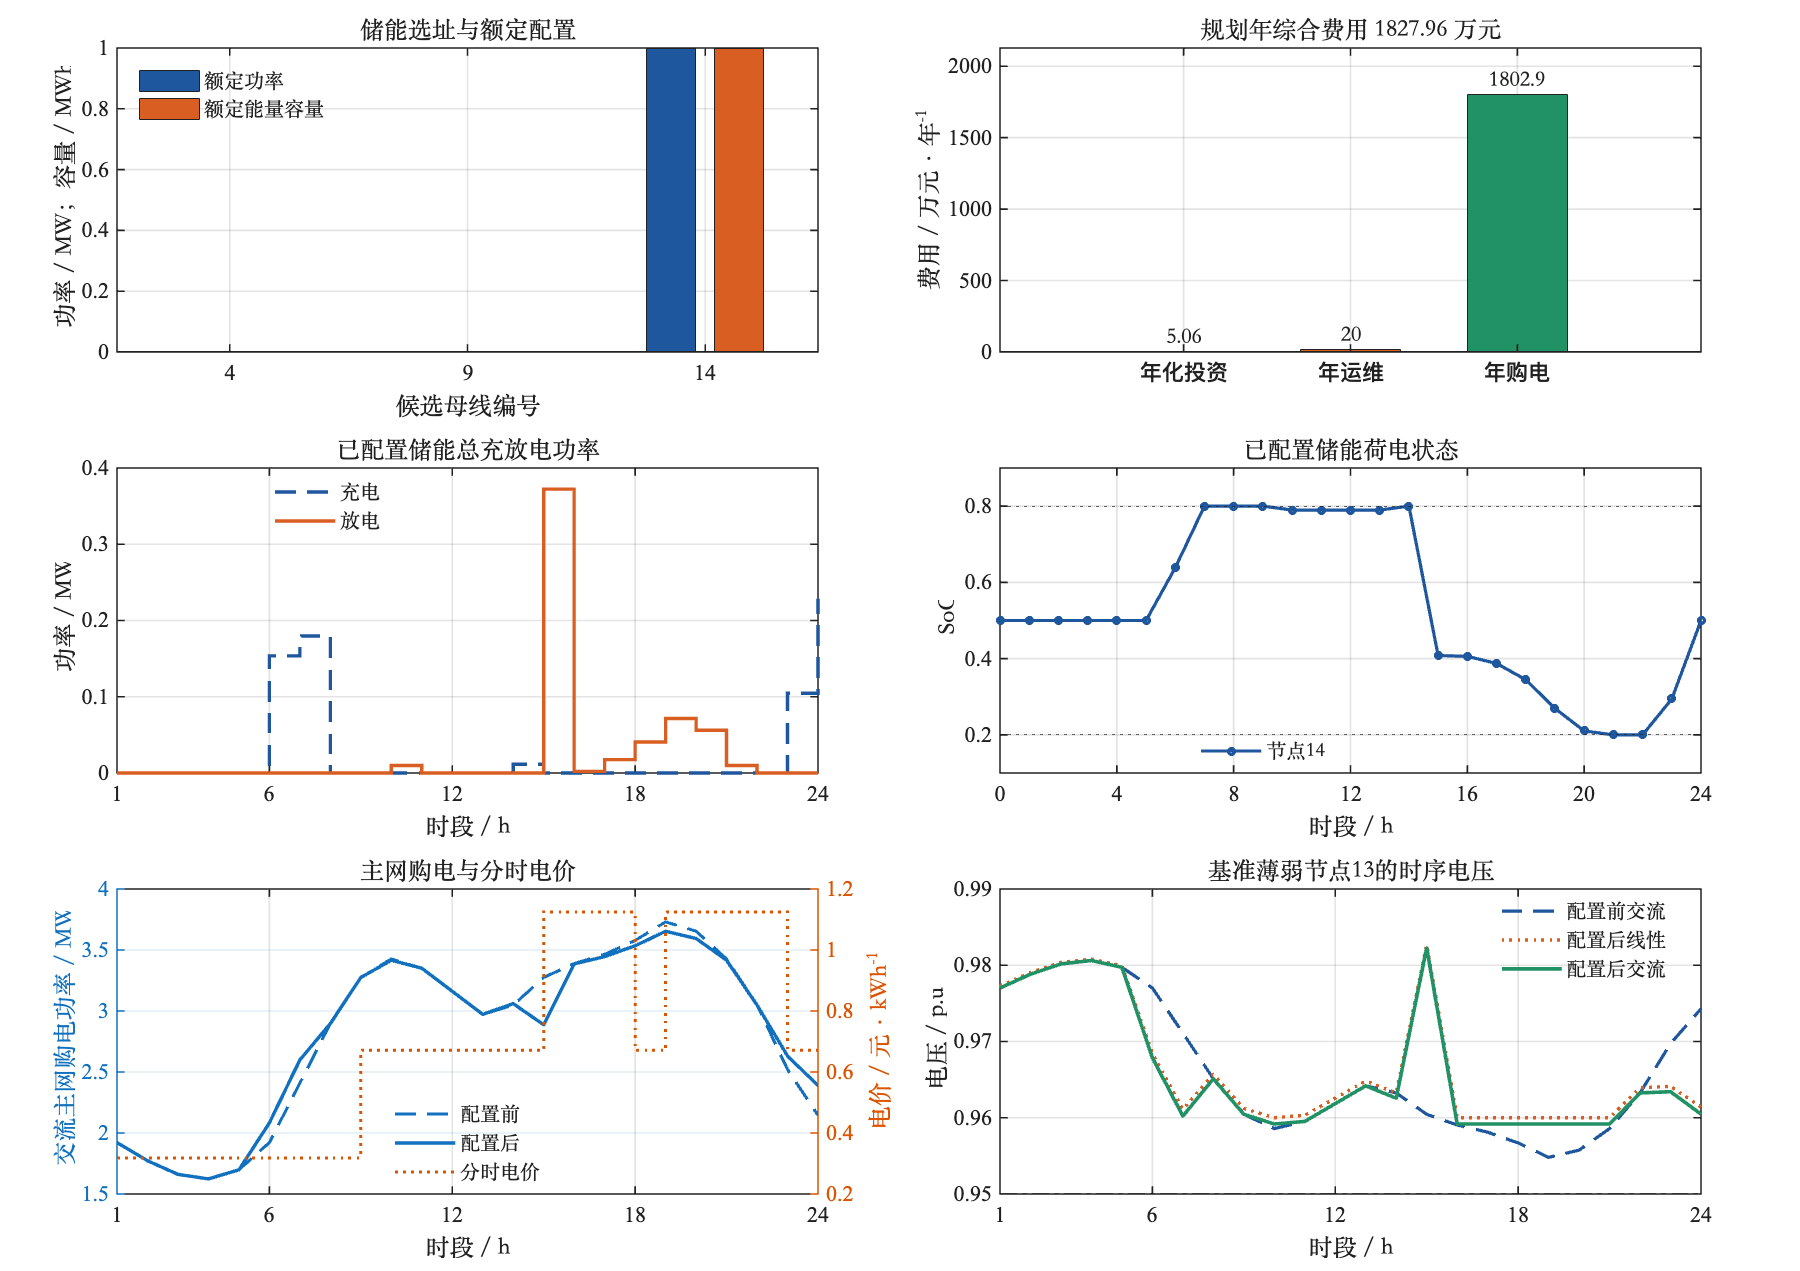

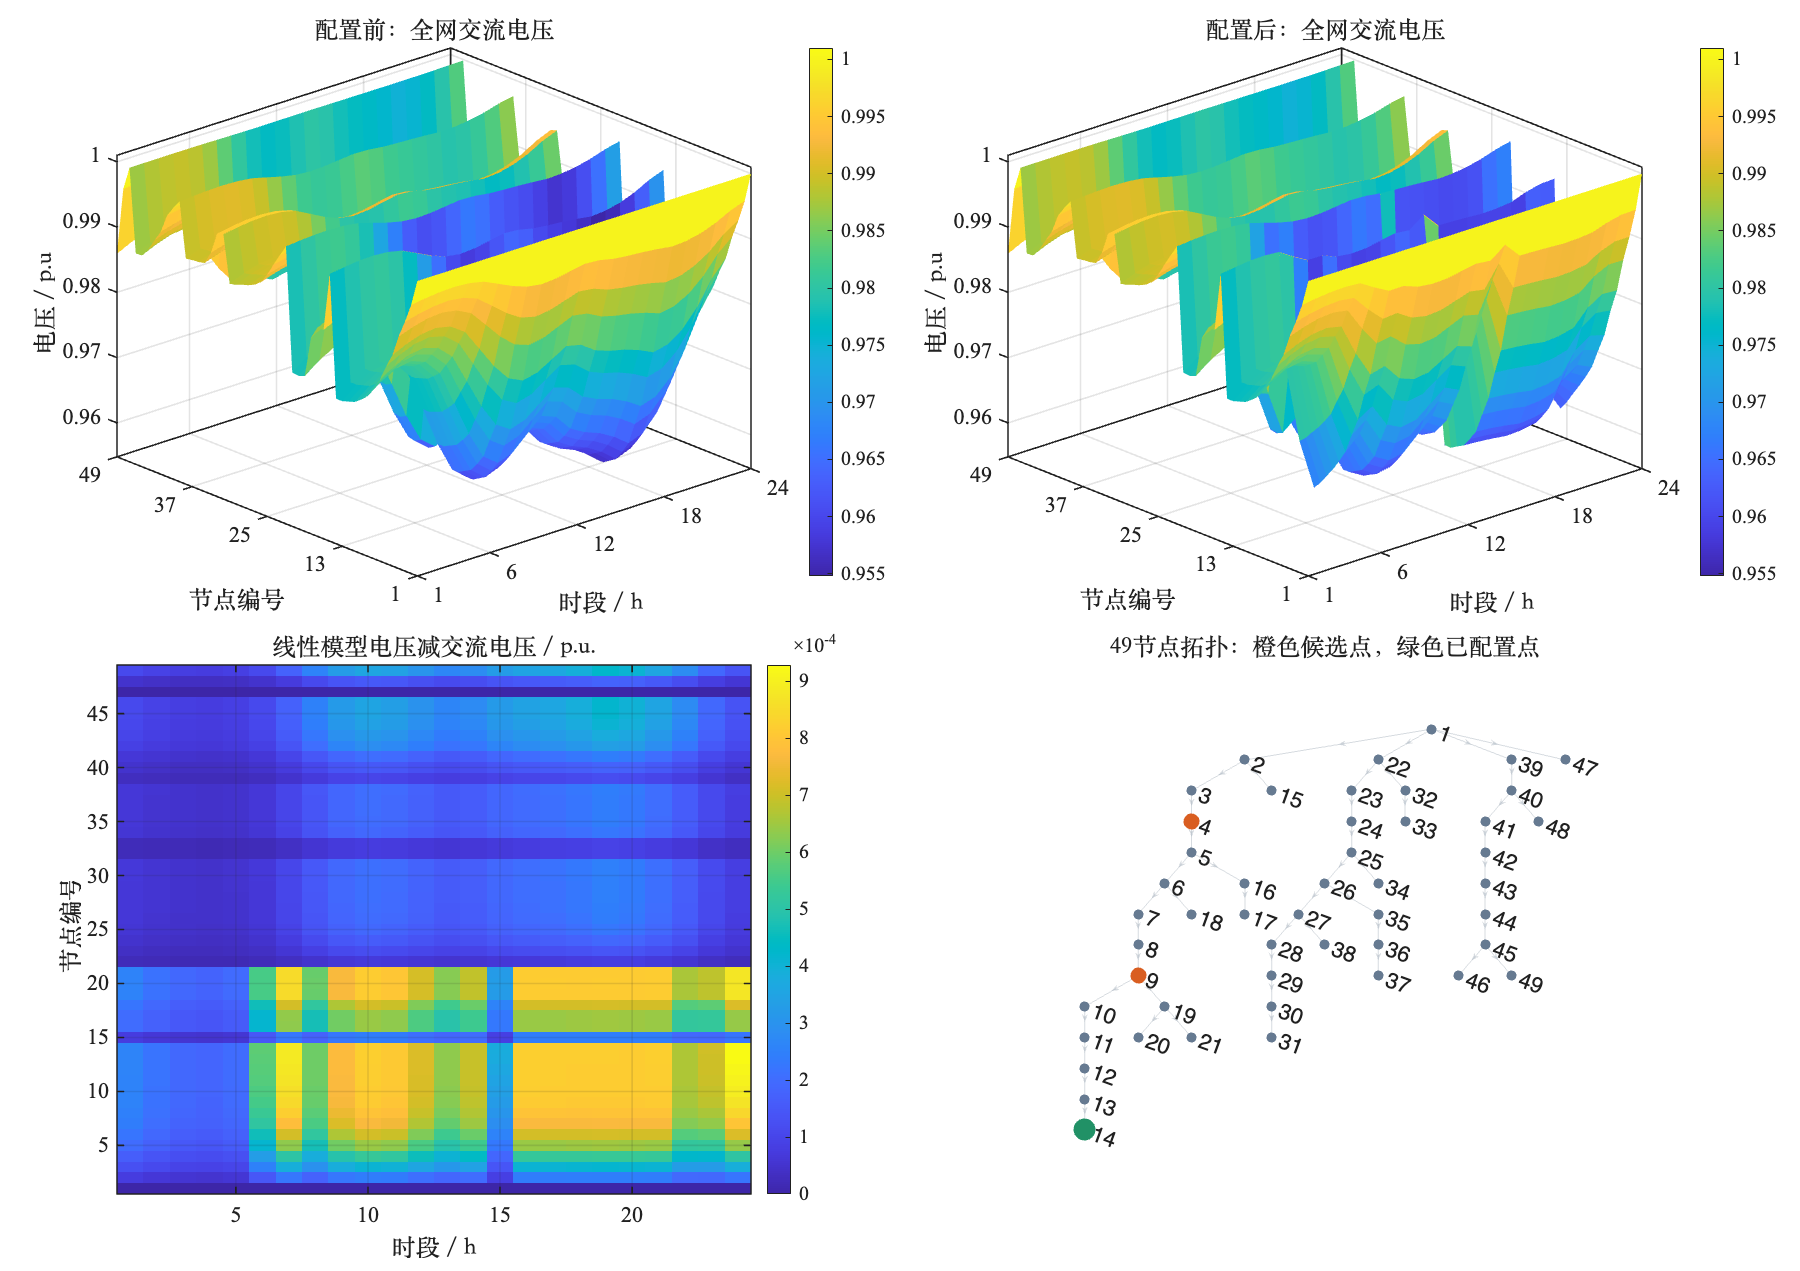

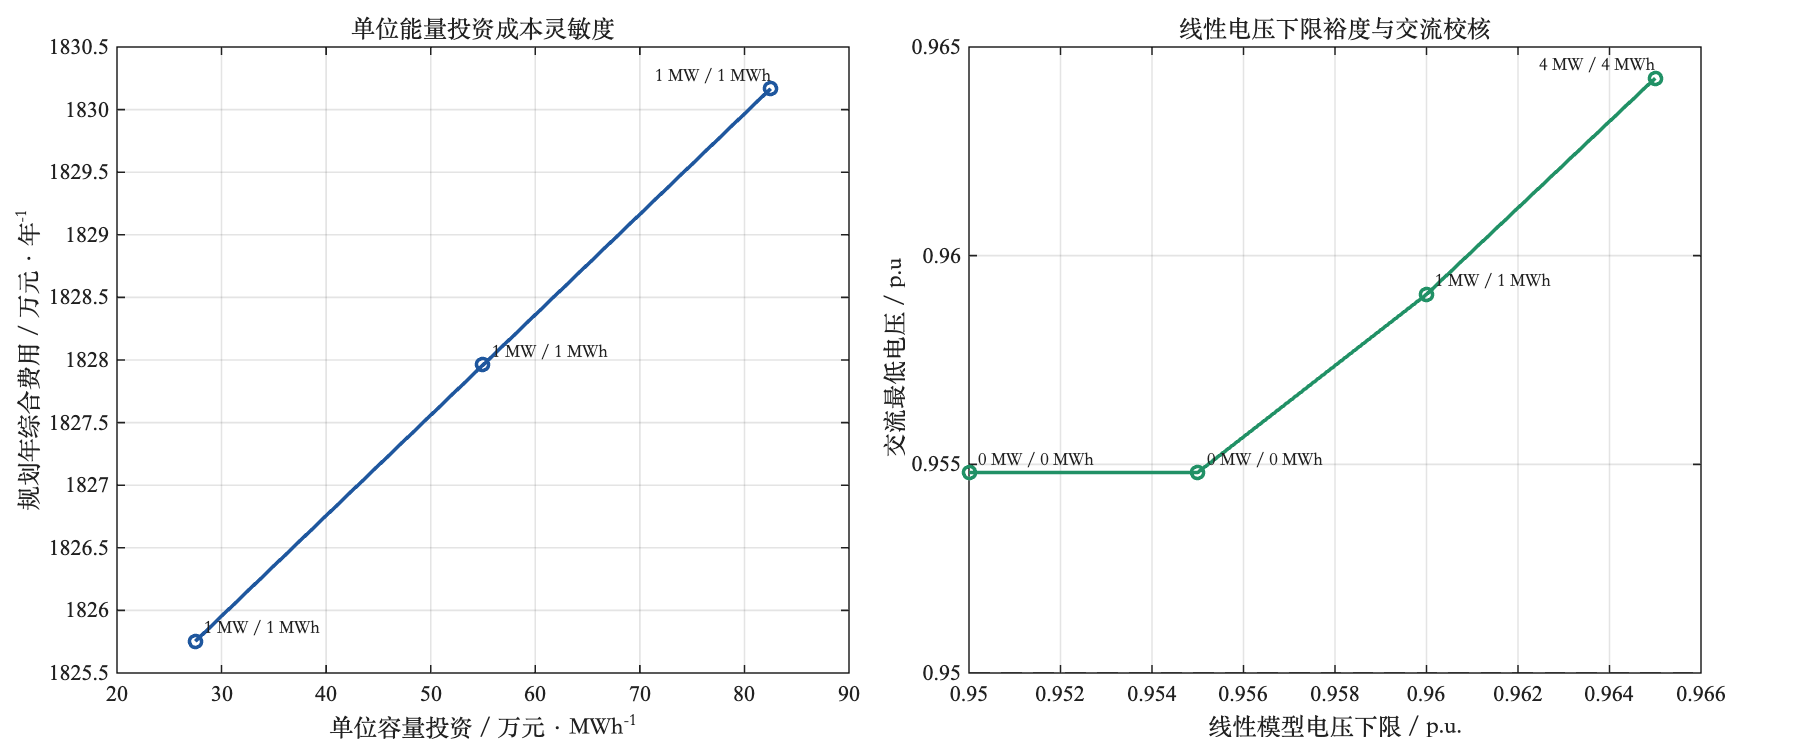

ess_week2_figures(Week2,script_dir);

writetable(Planning_Results,fullfile(script_dir,'Planning_206221321.csv'));
writetable(Sensitivity,fullfile(script_dir,'Sensitivity_206221321.csv'));
Hourly=table((1:P.T)',P.Price(:)/1000,Week2.Grid_MW(:),...
    Week2.AC.Grid_MW(:),sum(Week2.Pch_MW,1)',sum(Week2.Pdis_MW,1)',...
    min(Week2.AC.Voltage_pu,[],1)',max(Week2.AC.Voltage_pu,[],1)',...
    'VariableNames',{'Hour','Price_YuanPerKWh','GridLin_MW','GridAC_MW',...
    'Charge_MW','Discharge_MW','MinACVoltage_pu','MaxACVoltage_pu'});
writetable(Hourly,fullfile(script_dir,'Hourly_206221321.csv'));
Day4=Week2;
summary_file=fullfile(script_dir,'result_summary.mat');
if isfile(summary_file)
    previous=load(summary_file);
    for field={'Day1','Day2','Day3'}
        if isfield(previous,field{1})
            old=previous.(field{1});
            if isfield(old,'StudentID'),assert(strcmp(old.StudentID,Stu_ID));end
        end
    end
    save(summary_file,'Week2','Day4','Planning_Results','Sensitivity','-append');
else
    save(summary_file,'Week2','Day4','Planning_Results','Sensitivity');
end
fid=fopen(fullfile(script_dir,'Week2_206221321.json'),'w');
assert(fid~=-1); fwrite(fid,jsonencode(Week2),'char'); fclose(fid);
fprintf('TASK4_206221321_NATIVE_VALIDATED\n');

TASK4_206221321_NATIVE_VALIDATED


## 局部函数：规划模型

function R=solve_planning(P)
yalmip('clear');
nb=size(P.mpc.bus,1); nl=size(P.mpc.branch,1);
ns=numel(P.Candidate_Buses); nk=numel(P.Popt); T=P.T;
f=P.mpc.branch(:,1); t=P.mpc.branch(:,2);
r=P.mpc.branch(:,3); x=P.mpc.branch(:,4); Sbase=P.mpc.baseMVA;
Af=sparse(f,1:nl,1,nb,nl); At=sparse(t,1:nl,1,nb,nl);
E=sparse(P.Candidate_Buses,1:ns,1,nb,ns);
root=find(P.mpc.bus(:,2)==3); assert(numel(root)==1);
eroot=sparse(root,1,1,nb,1);
z=binvar(ns,1,'full'); w=binvar(ns,nk,'full');
Pr=w*P.Popt(:); Er=w*P.Eopt(:);
Pch=sdpvar(ns,T,'full'); Pdis=sdpvar(ns,T,'full');
u=binvar(ns,T,'full'); soc=sdpvar(ns,T+1,'full');
delta=sdpvar(ns,nk,T+1,'full');
Pb=sdpvar(nl,T,'full'); Qb=sdpvar(nl,T,'full');
U=sdpvar(nb,T,'full'); Pg=sdpvar(1,T,'full'); Qg=sdpvar(1,T,'full');
C=[sum(w,2)==z,0<=Pch,0<=Pdis,...
    Pch<=repmat(Pr,1,T),Pdis<=repmat(Pr,1,T),...
    Pch<=max(P.Popt)*u,Pdis<=max(P.Popt)*(1-u),...
    P.SoCmin<=soc<=P.SoCmax,soc(:,1)==P.SoC0,soc(:,end)==P.SoC0];
for h=1:T+1
    s=repmat(soc(:,h),1,nk); d=delta(:,:,h);
    C=[C,P.SoCmin*w<=d,d<=P.SoCmax*w,...
        s-P.SoCmax*(1-w)<=d,d<=s-P.SoCmin*(1-w)]; %#ok<AGROW>
end
for h=1:T
    C=[C,(delta(:,:,h+1)-delta(:,:,h))*P.Eopt(:)==...
        (P.EtaCharge*Pch(:,h)-Pdis(:,h)/P.EtaDischarge)*P.dt]; %#ok<AGROW>
end
C=[C,(At-Af)*Pb+eroot*Pg==P.Pload+E*(Pch-Pdis),...
    (At-Af)*Qb+eroot*Qg==P.Qload,...
    U(t,:)==U(f,:)-2*(diag(r)*Pb+diag(x)*Qb)/Sbase,...
    U(root,:)==1,P.VminLin^2<=U<=P.VmaxLin^2,...
    P.mpc.gen(1,10)<=Pg<=P.mpc.gen(1,9),...
    P.mpc.gen(1,5)<=Qg<=P.mpc.gen(1,4)];
Cinv=P.CRF*(P.CostPower*sum(Pr)+P.CostEnergy*sum(Er));
Com=P.CostOM*sum(Pr);
Cgrid=P.DaysPerYear*sum(P.Price.*Pg)*P.dt;
objective=Cinv+Com+Cgrid;
native_dir=fullfile(matlabroot,'toolbox','optim','optim');
original_path=path; restore_path=onCleanup(@()path(original_path)); %#ok<NASGU>
addpath(native_dir,'-begin');
assert(startsWith(which('intlinprog'),matlabroot));
ops=sdpsettings('solver','intlinprog','verbose',0,'savesolveroutput',1);
ops.intlinprog.RelativeGapTolerance=1e-7;
ops.intlinprog.AbsoluteGapTolerance=1e-9;
ops.intlinprog.MaxTime=600;
timer=tic; sol=optimize(C,objective/1e6,ops); seconds=toc(timer);
assert(sol.problem==0,'选址定容求解失败：%s',sol.info);
R=struct('Build',value(z),'Options',value(w),'PowerRating_MW',value(Pr),...
    'EnergyRating_MWh',value(Er),'Pch_MW',value(Pch),'Pdis_MW',value(Pdis),...
    'ChargeMode',value(u),'SoC',value(soc),'Delta',value(delta),...
    'BranchP_MW',value(Pb),'BranchQ_Mvar',value(Qb),...
    'VoltageLin_pu',sqrt(value(U)),'Grid_MW',value(Pg),'GridQ_Mvar',value(Qg),...
    'AnnualInvestment_Yuan',value(Cinv),'AnnualOM_Yuan',value(Com),...
    'AnnualGridCostLin_Yuan',value(Cgrid),'AnnualTotalCost_Yuan',value(objective),...
    'Solver','MATLAB intlinprog (YALMIP)','SolverStatus',sol.problem,...
    'SolverInfo',sol.info,'SolveSeconds',seconds,'SolverOutput',sol.solveroutput);
assert(all(isfinite(R.VoltageLin_pu),'all'));
end

function A=ac_check(P,pch,pdis)
nb=size(P.mpc.bus,1); ns=numel(P.Candidate_Buses);
E=sparse(P.Candidate_Buses,1:ns,1,nb,ns);
V=zeros(nb,P.T); loss=zeros(1,P.T); pg=zeros(1,P.T); success=false(1,P.T);
options=mpoption('verbose',0,'out.all',0,'pf.alg','NR');
for h=1:P.T
    c=P.mpc; c.bus(:,3)=P.Pload(:,h)+E*(pch(:,h)-pdis(:,h));
    c.bus(:,4)=P.Qload(:,h);
    pf=runpf(c,options); success(h)=logical(pf.success);
    assert(success(h),'第%d时段交流潮流未收敛。',h);
    V(:,h)=pf.bus(:,8); loss(h)=sum(pf.branch(:,14)+pf.branch(:,16));
    pg(h)=sum(pf.gen(:,2));
end
[vmin,loc]=min(V(:)); [bus,h]=ind2sub(size(V),loc);
A=struct('Voltage_pu',V,'Grid_MW',pg,'Loss_MW',loss,'Converged',success,...
    'MinVoltage_pu',vmin,'MinBus',P.mpc.bus(bus,1),'MinHour',h,...
    'MaxVoltage_pu',max(V(:)),'DailyLoss_MWh',sum(loss)*P.dt,...
    'AnnualGridCost_Yuan',P.DaysPerYear*sum(P.Price.*pg)*P.dt);
end

function [V,pg]=linear_baseline(P)
nb=size(P.mpc.bus,1); nl=size(P.mpc.branch,1);
f=P.mpc.branch(:,1); t=P.mpc.branch(:,2);
B=sparse(t,1:nl,1,nb,nl)-sparse(f,1:nl,1,nb,nl);
root=find(P.mpc.bus(:,2)==3); free=setdiff(1:nb,root);
pb=B(free,:)\P.Pload(free,:); qb=B(free,:)\P.Qload(free,:);
drop=2*(diag(P.mpc.branch(:,3))*pb+diag(P.mpc.branch(:,4))*qb)/P.mpc.baseMVA;
U=ones(nb,P.T); U(free,:)=B(free,:)'\(-drop-B(root,:)'*ones(1,P.T));
V=sqrt(U); pg=sum(P.Pload,1);
end

function K=validate_planning(P,R)
ns=numel(P.Candidate_Buses); T=P.T; nk=numel(P.Popt);
nonnegative=max([0;-R.Pch_MW(:);-R.Pdis_MW(:)]);
power=max([0;reshape(R.Pch_MW-repmat(R.PowerRating_MW,1,T),[],1);...
    reshape(R.Pdis_MW-repmat(R.PowerRating_MW,1,T),[],1)]);
energy=diff(R.SoC,1,2).*repmat(R.EnergyRating_MWh,1,T)-...
    (P.EtaCharge*R.Pch_MW-R.Pdis_MW/P.EtaDischarge)*P.dt;
delta_error=0;
for h=1:T+1
    delta_error=max(delta_error,max(abs(R.Delta(:,:,h)-...
        repmat(R.SoC(:,h),1,nk).*R.Options),[],'all'));
end
nb=size(P.mpc.bus,1); nl=size(P.mpc.branch,1);
f=P.mpc.branch(:,1); t=P.mpc.branch(:,2);
B=sparse(t,1:nl,1,nb,nl)-sparse(f,1:nl,1,nb,nl);
E=sparse(P.Candidate_Buses,1:ns,1,nb,ns);
root=find(P.mpc.bus(:,2)==3); e=sparse(root,1,1,nb,1);
pbal=B*R.BranchP_MW+e*R.Grid_MW-P.Pload-E*(R.Pch_MW-R.Pdis_MW);
qbal=B*R.BranchQ_Mvar+e*R.GridQ_Mvar-P.Qload;
ures=R.VoltageLin_pu(t,:).^2-R.VoltageLin_pu(f,:).^2+...
    2*(diag(P.mpc.branch(:,3))*R.BranchP_MW+...
    diag(P.mpc.branch(:,4))*R.BranchQ_Mvar)/P.mpc.baseMVA;
K=struct('MaxEnergyResidual_MWh',max(abs(energy),[],'all'),...
    'MaxBigMProductError',delta_error,'MaxPowerViolation_MW',power,...
    'MaxNonnegativeViolation_MW',nonnegative,...
    'MaxSimultaneousPower_MW',max(min(R.Pch_MW,R.Pdis_MW),[],'all'),...
    'InitialSoCError',max(abs(R.SoC(:,1)-P.SoC0)),...
    'TerminalSoCError',max(abs(R.SoC(:,end)-P.SoC0)),...
    'SoCViolation',max([0;P.SoCmin-R.SoC(:);R.SoC(:)-P.SoCmax]),...
    'IntegerViolation',max(abs([R.Build(:);R.Options(:);R.ChargeMode(:)]-...
        round([R.Build(:);R.Options(:);R.ChargeMode(:)]))),...
    'OptionSumError',max(abs(sum(R.Options,2)-R.Build)),...
    'MaxActivePowerBalance_MW',max(abs(pbal),[],'all'),...
    'MaxReactivePowerBalance_Mvar',max(abs(qbal),[],'all'),...
    'MaxVoltageEquationResidual',max(abs(ures),[],'all'),...
    'ModelVoltageViolation',max([0;P.VminLin-R.VoltageLin_pu(:);R.VoltageLin_pu(:)-P.VmaxLin]),...
    'ACVoltageViolation',max([0;P.VminAC-R.AC.Voltage_pu(:);R.AC.Voltage_pu(:)-P.VmaxAC]),...
    'MaxACVoltageError_pu',max(abs(R.AC.Voltage_pu-R.VoltageLin_pu),[],'all'));
checked=rmfield(K,'MaxACVoltageError_pu');
K.Passed=all(structfun(@(v)v<1e-6,checked)) && all(R.AC.Converged);
end